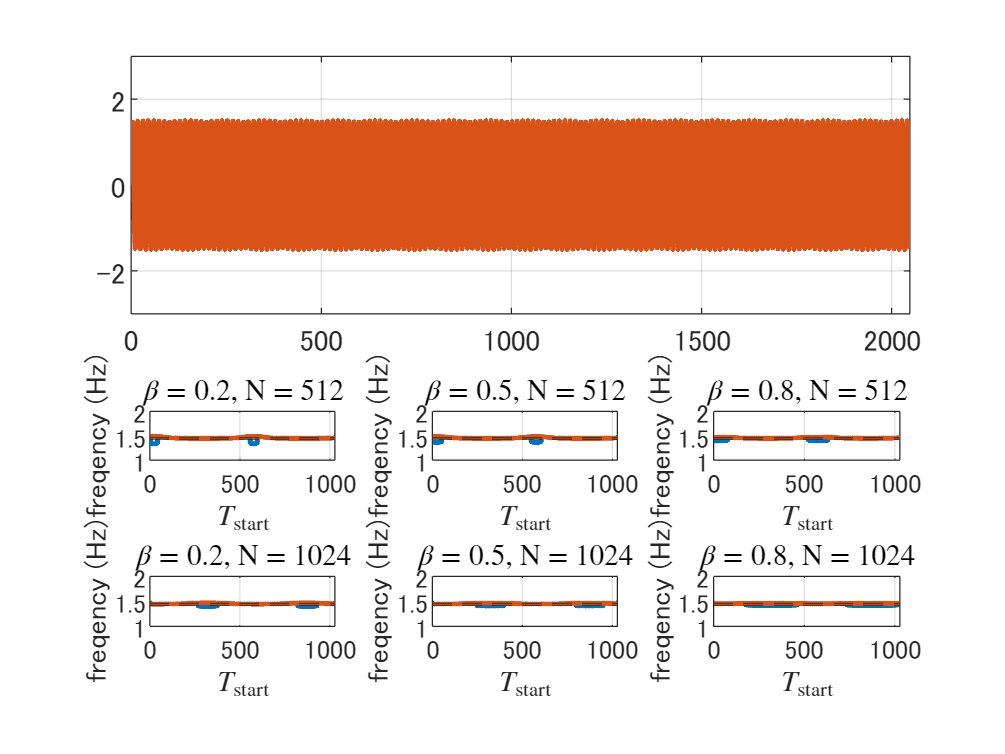

t = 0:2048;
dt = 0.05;
subplot(2,1,1)
f1 = 1.4239;
f2 = 1.5060;
f2 = 1.443;
plot(t, sin(2*pi*f1*dt*t))
hold on
plot(t, 1.5*sin(2*pi*f2*dt*t))
ylim([-3 3])
xlim([0,2048])
hold off

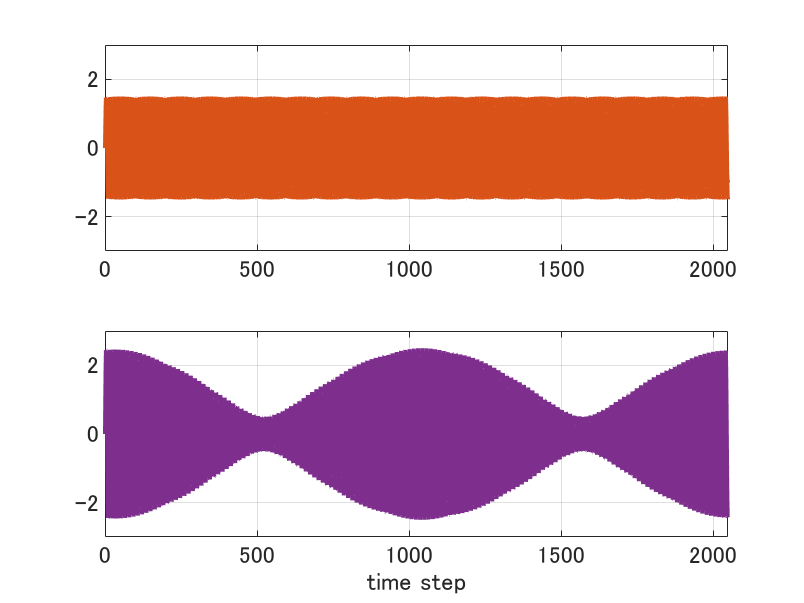

subplot(2,1,2)
u = sin(2*pi*f1*dt*t)+1.5*sin(2*pi*f2*dt*t);
plot(t, u,'Color',"#7E2F8E")
ylim([-3 3])
hold off
xlabel("time step")
xlim([0,2048])

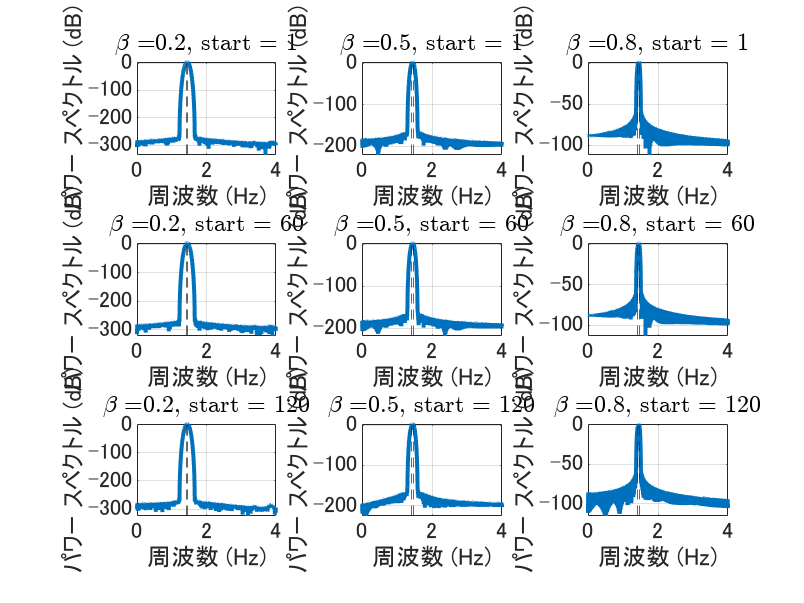

set(0,"DefaultAxesFontSize",13);    % フォントサイズ13
set(0,"DefaultLineLineWidth",2);    % 線の太さ2
set(0,"DefaultAxesXGrid",'on');     % X軸方向のグリッドON
set(0,"DefaultAxesYGrid",'on');     % Y軸方向のグリッドON

beta_list = [0.2 0.5 0.8];
T_fft_list = [128 256 512 1024];
start_list = [1 60 120];
%figure('Position', [100 100 400 300]);
figure('Position', [100 100 960 720])
for j = 1:length(T_fft_list)
    for i = 1:length(beta_list)
        for k = 1:length(start_list)
            subplot(length(beta_list),length(start_list),3*(k-1)+i)
            N = T_fft_list(j);
            t_start = start_list(k);
            beta = beta_list(i);
            pspectrum(u(t_start:t_start+(N-1)),0:dt:dt*(N-1),'Leakage',beta)
            xline([f1 f2],'--')
            xlim([0 4])
            %saveas(gcf,"pspectrum_beta_"+string(beta)+"_T_fft_"+string(N)+"_start_"+string(t_start)+".png")
            title("$\beta = $"+string(beta)+", start = "+string(t_start),'Interpreter','latex')
        end
    end
    saveas(gcf,"pspectrum_T_fft_"+string(N)+".png")
end

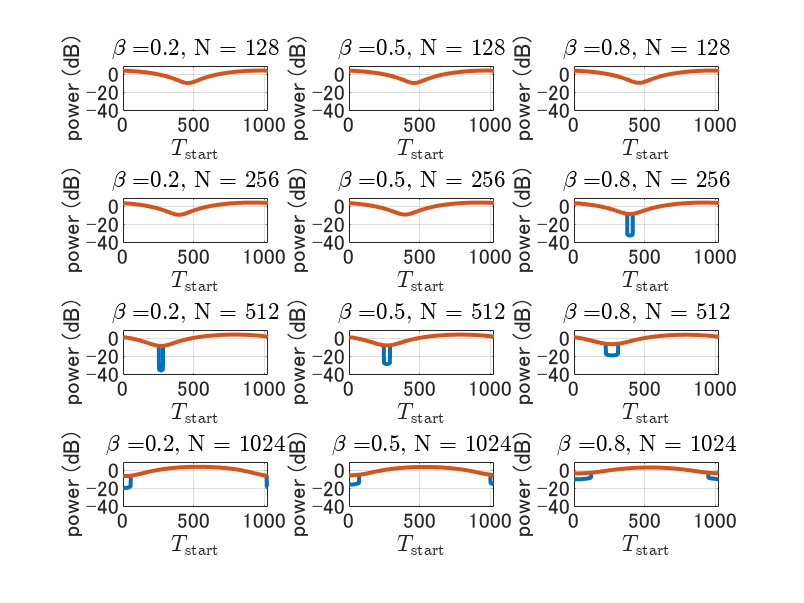

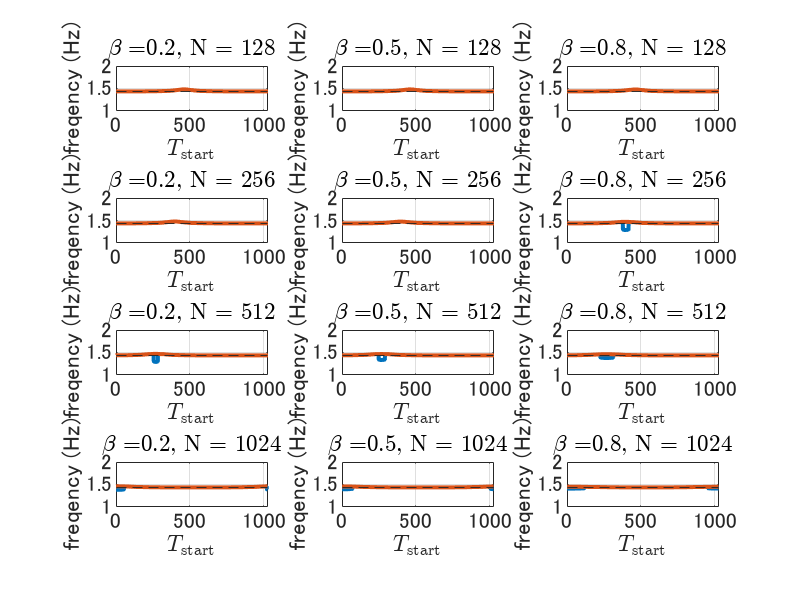

beta_list = [0.2 0.5 0.8];
T_fft_list = [128 256 512 1024];
fig1 = figure('Position', [100 100 960 720]);
fig2 = figure('Position', [100 100 960 720]);
%figure('Position', [100 100 960 720])
for j = 1:length(T_fft_list)
    N = T_fft_list(j);
    for i = 1:length(beta_list)
        beta = beta_list(i);
        t_start_max = length(u)-N;
        freqs = zeros(2,t_start_max);
        powers = zeros(2,t_start_max);
        for t_start = 1:t_start_max       
            [p,f] = pspectrum(u(t_start:t_start+(N-1)),0:dt:dt*(N-1),'Leakage',beta);
            p = 10*log10(p);
            [pks,locs] = findpeaks(p,f,'MinPeakHeight',-40);
            if length(pks) == 1     % ピーク一個だったら第二も第一も同じに
                pks(end+1) = pks(1);
                locs(end+1) = locs(1);
            end
            freqs(:,t_start) = locs;
            powers(:,t_start) = pks;
        end
        figure(fig1);
        subplot(length(T_fft_list),length(beta_list),3*(j-1)+i);
        plot(1:t_start_max, powers);
        xlabel("$T_{\rm start}$",'Interpreter','latex');
        ylabel("power (dB)");
        title("$\beta = $"+string(beta)+", N = "+string(N),'Interpreter','latex');
        xlim([0,1028])
        ylim([-40 10])
        figure(fig2);
        subplot(length(T_fft_list),length(beta_list),3*(j-1)+i);
        plot(1:t_start_max, freqs);
        xlabel("$T_{\rm start}$",'Interpreter','latex');
        ylabel("freqency (Hz)");
        yline([f1 f2],'--');
        xlim([0,1028])
        ylim([1 2])
        title("$\beta = $"+string(beta)+", N = "+string(N),'Interpreter','latex');
    end
    saveas(fig1,"pspectrum_power.png")
    saveas(fig2,"pspectrum_freq.png")
end

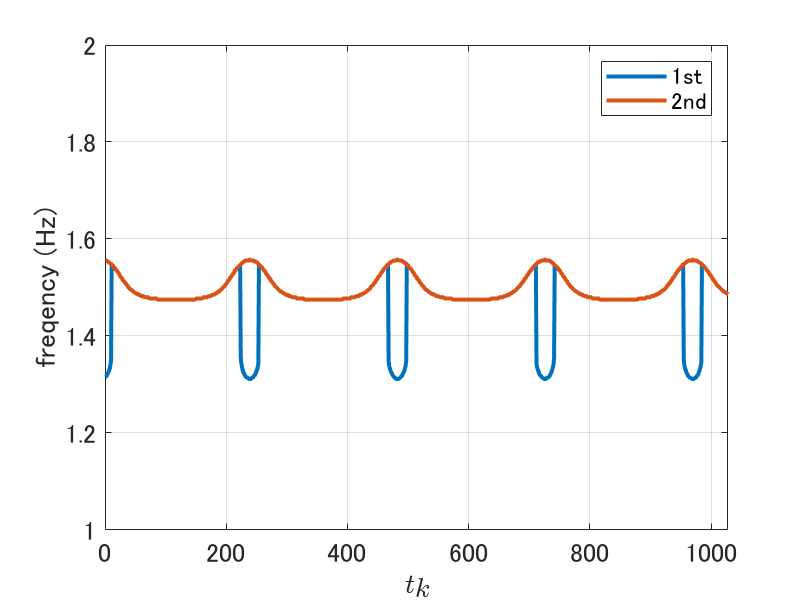

beta = 0.5;
N = 256;
t_start_max = length(u)-N;
freqs = zeros(2,t_start_max);
powers = zeros(2,t_start_max);
for t_start = 1:t_start_max       
    [p,f] = pspectrum(u(t_start:t_start+(N-1)),0:dt:dt*(N-1),'Leakage',beta);
    p = 10*log10(p);
    [pks,locs] = findpeaks(p,f,'MinPeakHeight',-40);
    if length(pks) == 1     % ピーク一個だったら第二も第一も同じに
        pks(end+1) = pks(1);
        locs(end+1) = locs(1);
    end
    freqs(:,t_start) = locs;
    powers(:,t_start) = pks;
end
figure
plot(1:t_start_max, freqs);
xlabel("$t_k$",'Interpreter','latex');
ylabel("freqency (Hz)");
%title("$\beta = $"+string(beta)+", N = "+string(N),'Interpreter','latex');
xlim([0,1028])
ylim([1 2])
legend(["1st","2nd"])

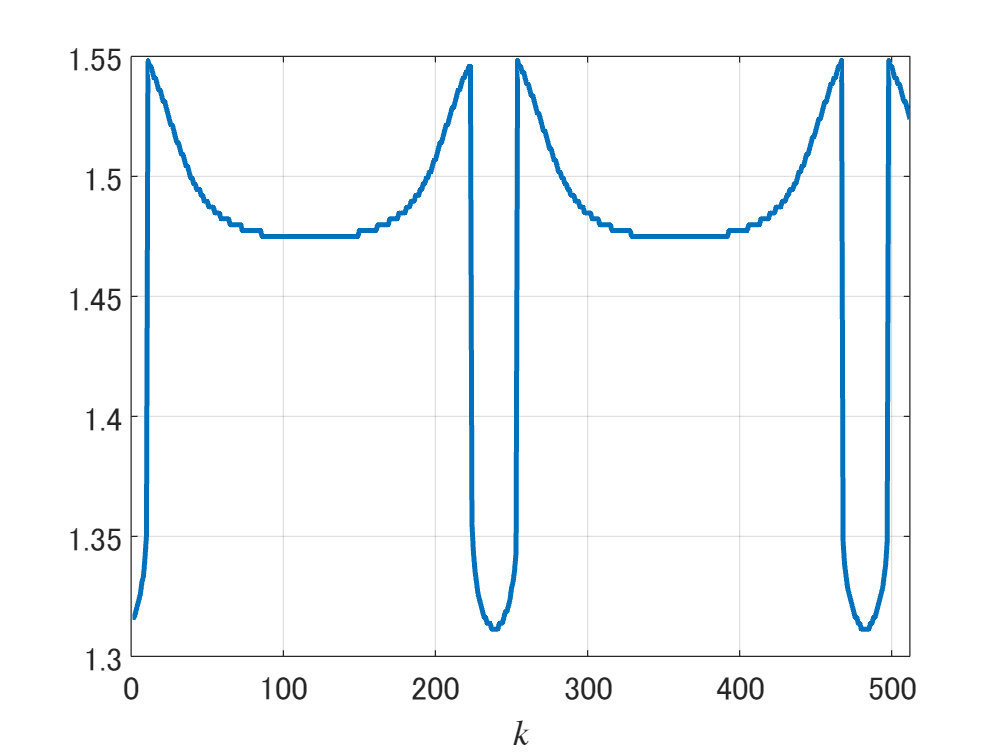


pos = 1;
N_col = 512;
u_ = freqs(1,pos:pos+N_col-1);
%u_ = ones(N,1); 
%theta = -5:0.1:5;
%u_ = abs(sin(0.5*theta));
[r, lags] = xcorr(u_-mean(u_),'coeff');
%[r, lags] = xcorr(u_,'coeff');
plot(u_)
xlabel("$k$",'Interpreter','latex')
xlim([0 N_col])

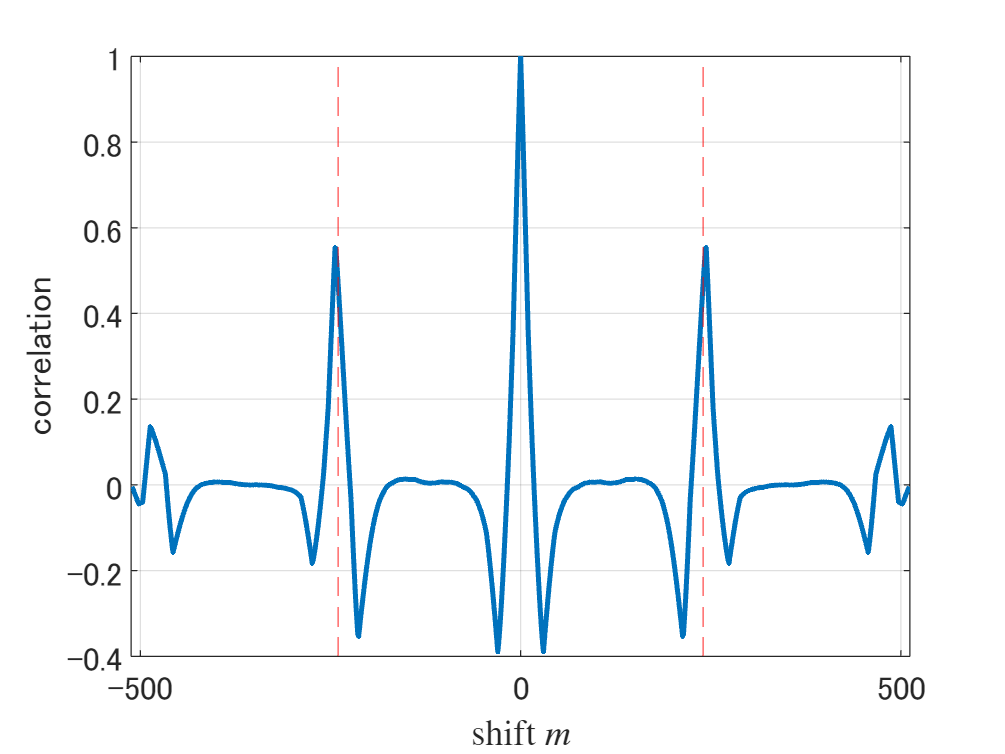

plot(lags,r)
xlabel("shift $m$",'Interpreter','latex')
ylabel("correlation")
xline([240,-240],'r--')
xlim([-N_col N_col])

figure
beta_list = [0 0.2 0.5 0.8 1.0]

beta_list =          0    0.2000    0.5000    0.8000    1.0000


for i = 1:length(beta_list)
    plot(kaiser(256,beta_list(i)))
    hold on
end
xlim([1 256])
l = legend("$\beta = "+string(beta_list)+"$",'Interpreter','latex')

l =   Legend ($\beta = 0$, $\beta = 0.2$, $\beta = 0.5$, $\beta = 0.8$, $\beta = 1$) のプロパティ:

         String: {'$\beta = 0$'  '$\beta = 0.2$'  '$\beta = 0.5$'  '$\beta = 0.8$'  '$\beta = 1$'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 11.7000
       Position: [0.7047 0.6629 0.1810 0.2371]
          Units: 'normalized'

  すべてのプロパティ を表示


l.NumColumns = 3

l =   Legend ($\beta = 0$, $\beta = 0.2$, $\beta = 0.5$, $\beta = 0.8$, $\beta = 1$) のプロパティ:

         String: {'$\beta = 0$'  '$\beta = 0.2$'  '$\beta = 0.5$'  '$\beta = 0.8$'  '$\beta = 1$'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 11.7000
       Position: [0.3643 0.8001 0.5214 0.0999]
          Units: 'normalized'

  すべてのプロパティ を表示


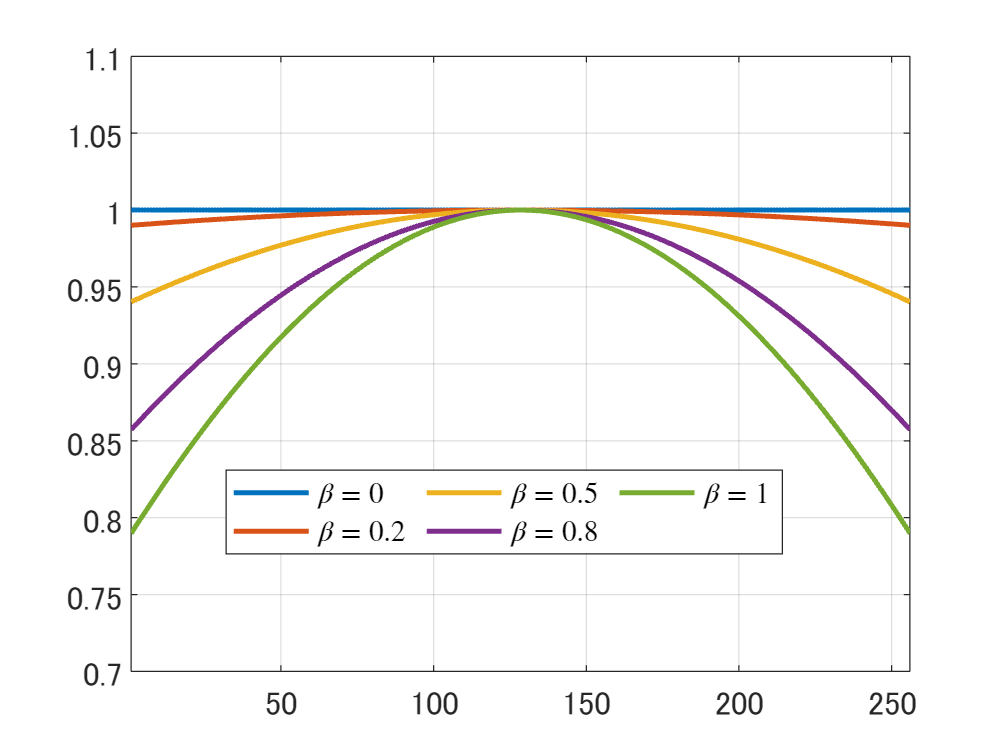

hold off
ylim([0.7 1.1])